# Hierarchical Risk Parity Exploration

Copyright 2019 The MathWorks, Inc.

#### Introduction

This example presents the full workflow to perform asset allocation using hierarchical risk parity analysis (HRP) in MATLAB. HRP is proposed by Lopez de Prado [Ref 1]. It is a variation of the original concept 'risk parity' and diversifies the assets according to a hierarchical tree structure. It does not require the invertibility of the covariance matrix, as compared to Mean-Variance portfolio framework. Therefore, it produces more stable and diversified asset allocations [Ref 1].

This example will walk you through the steps to build an asset allocation strategy based on HRP. You will: 

- Learn how to use statistics and machine learning techniques to cluster assets into a hierarchical tree structure.

- Understand how to develop allocation strategies based on the tree structure and risk parity concept through recursion.

- Compare its result with Mean-Variance asset allocation. 

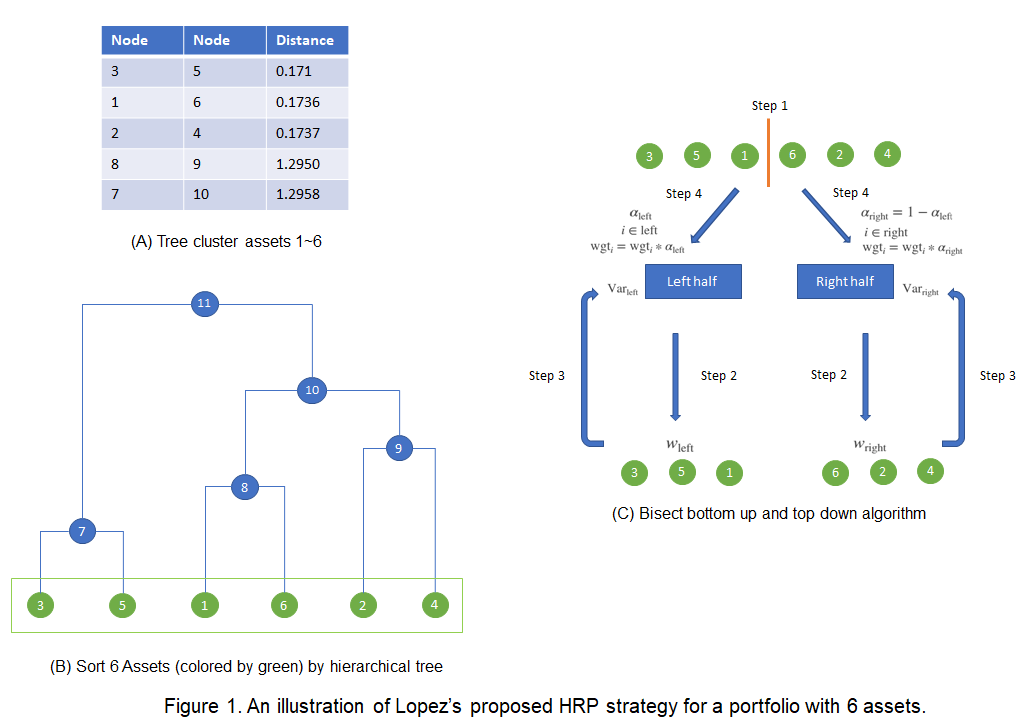

This example explains in detail HRP strategy shown in the above figure. The functions that wrap the implementation details are also provided in the folder, so you can directly call them in your workflow.

#### Load data

The dataset is simulated that some assets are closely correlated.

assetRetn = csvread("./retns_assets.txt");
[nSample, nAssets] = size(assetRetn);
table(nSample, nAssets)

ans = 1×2 table
    nSample    nAssets
    _______    _______

     1000        14   


assetCovar = cov(assetRetn);

#### Hierarchical clustering

[Hierarchical clustering](https://www.mathworks.com/help/stats/hierarchical-clustering.html) [Ref 2] is a common clustering technique in machine learning. In the context of asset allocation, a hierarchical clustering algorithm is applied to find the distance or similarity between each pair of assets and group them into a multilevel binary hierarchical tree. Therefore, investment decisions can be made according to the hierarchical tree structure, which are not only intuitive but also stable [Ref 1]. 

Let's look at the correlation matrix of the asset universe. 

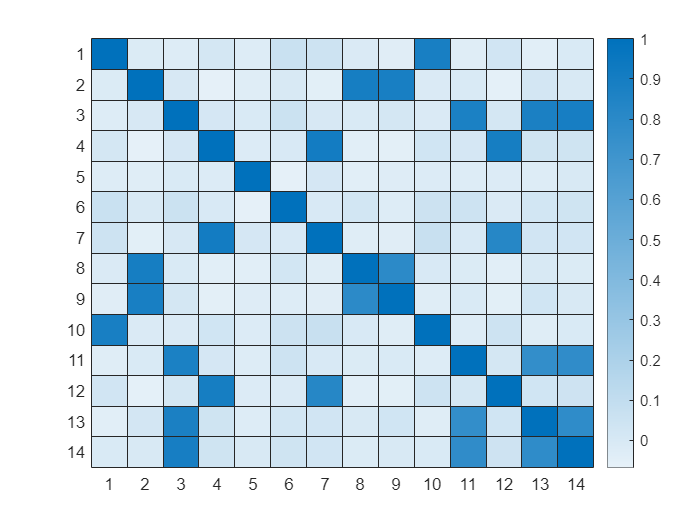

cr = corrcov(assetCovar);
heatmap(cr);

Hierarchical clustering technique is used to cluster the assets, so that the correlation or covariance matrix can be rearranged to be very close to a diagonal matrix. To perform the hierarchical clustering of the assets, the following steps are needed:

- Define the distance matrix based on the correlation matrix.

- Compute the linkage matrix for assets in the investment universe. 

- Group the assets by the linkage (quasi-diagonalization of correlation matrix).

Step 1, and 2 can be easily done by functions [linkage](https://www.mathworks.com/help/stats/linkage.html) in Statistics and Machine Learning Toolbox™ [Ref 2]. An example of linkage matrix for a 6 assets portfolio is shown in Figure 1.(A). You can also plot the dendrogram using the linkage result, in order to visualize the structure of the hierarchical tree. Function *dendrogram* is also available in Statistics and Machine Learning Toolbox™. Apply the step 1 and 2 on the 14 asset dataset:

% 1) compute the correlation distance matrix
distCorr = ((1-cr)/2).^0.5;

% 2) compute the linkage
link = linkage(distCorr, 'single', 'euclidean')

link =     4.0000    7.0000    0.3174
    2.0000    8.0000    0.3376
   12.0000   15.0000    0.3377
    1.0000   10.0000    0.3403
    9.0000   16.0000    0.3490
    3.0000   14.0000    0.3522
   13.0000   20.0000    0.3839
   11.0000   21.0000    0.3876
    5.0000    6.0000    1.0337
   18.0000   23.0000    1.0686


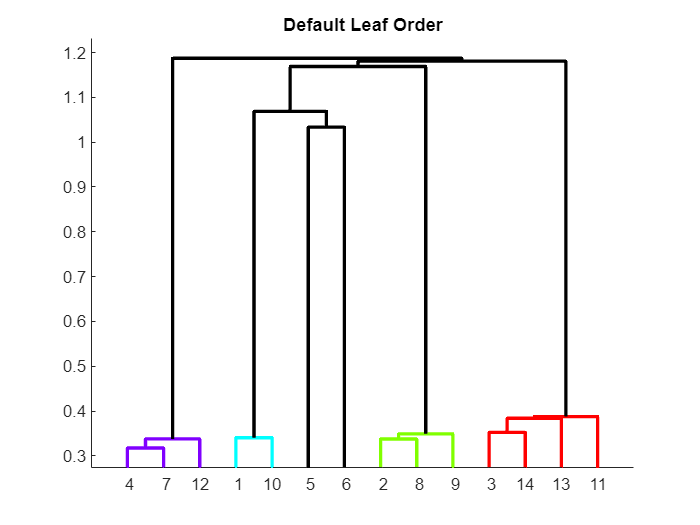

figure;
[H,~,~] = dendrogram(link,'Orientation','top','ColorThreshold','default');
set(H,'LineWidth',2);
title('Default Leaf Order');

Quasi-diagonalization is then performed on the correlation or covariance matrix based on the linkage matrix. As a result, the largest values lie along the diagonal and similar investments are placed together. This reordering of the asset list using the linkage matrix can be visualized in Figure 1.(B). You can visualize the correlation matrix after the quasi-diagonalization. This is a nice clustering of assets that are closely related.

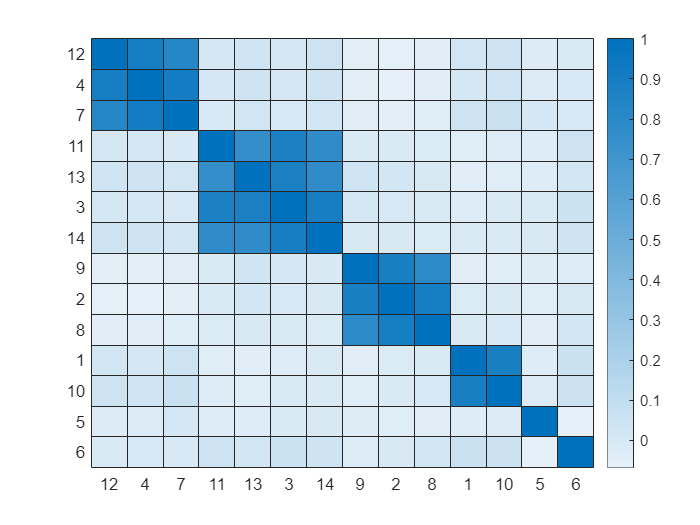

% 3) sort assets for quasi-diagonalization 
numLeafNodes = size(link, 1) + 1;
rootGroupNodeId = 2*numLeafNodes-1;
sortedIdx = getLeafNodesInGroup(rootGroupNodeId, link);
heatmap(cr(sortedIdx, sortedIdx), 'XData', sortedIdx, 'YData', sortedIdx );

#### Develop allocation strategies based on clustered groups

The steps above have applied hierarchical tree clustering and sorted the asset list for quasi-diagonalization, as illustrated in Figure 2. Now, given this tree structure, you are ready to allocate funds using the risk parity concept, which is named as "hierarchical risk parity". 

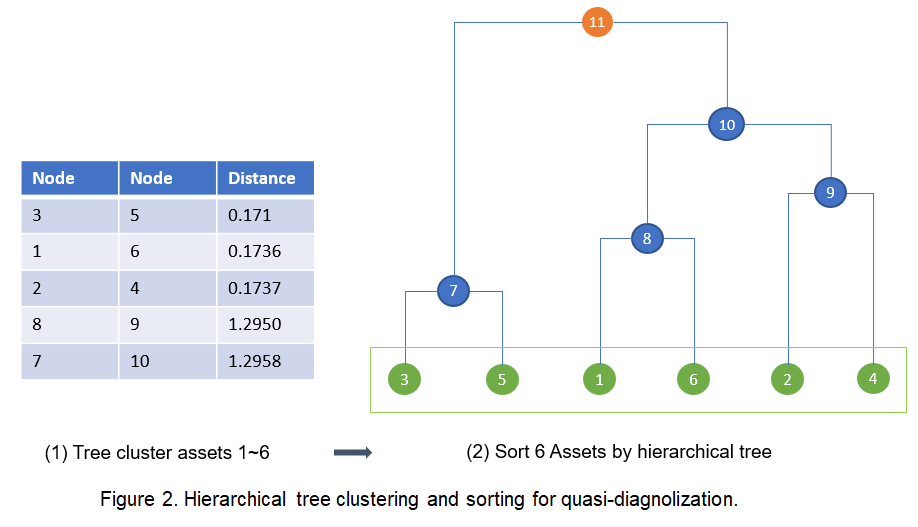 

Some ideas to motivate the risk parity allocation:

- Within a cluster or group, we can perform either a simple inverse variance allocation or an equal risk contribution allocation [Ref 4].

- You can use a pure bottom up approach to build the asset weights with the multilevel tree structure. A recursive algorithm is straightforward for a tree structure.

- You can use a bisect approach to allocate funds among assets according to Lopez's HRP paper [Ref 1]. It combines both the bottom up and top down approaches.

This example focuses on Lopez de Prado's proposed strategy. The strategy chooses the "inverse of variance" allocation when dealing with a group of assets, because the covariance matrix has been quasi-diagonalized by hierarchical clustering. Here is how the strategy works.

Initialize all asset weights ${\textrm{wgt}}_i =1,i=1,2,\ldotp \ldotp \ldotp n$. The recursive bisection algorithm starts with the full sorted asset list after quasi-diagnolization.

*Algorithm*: for current asset list, if it contains more than 1 asset.

- Divide the current list into left and right equal halves.

- Find $w_{\textrm{left}} \;$ for all assets in the left half, and $\;w_{\textrm{right}}$ for all assets in the right half based on inverse of variance $w_i =\frac{{1/\textrm{Var}}_i }{\sum \left({1/\textrm{Var}}_j \right)},j=\textrm{all}\;\textrm{assets}\;\textrm{in}\;\textrm{the}\;\textrm{group}$. Note that $\sum \left(w_{\textrm{left}} \right)=1,\sum \left(w_{\textrm{right}} \right)=1$.

- Compute the total variance ${\textrm{Var}}_{\textrm{left}} \;,\;\;{\textrm{Var}}_{\textrm{right}}$ of left and right halves with asset weights $w_{\textrm{left}} \;,\;\;w_{\textrm{right}}$ , by $\textrm{Var}=w^{\prime } \Sigma w$

- Compute the splitting factor $\alpha_{\textrm{left}} =\frac{{1/\textrm{Var}}_{\textrm{left}} }{{1/\textrm{Var}}_{\textrm{left}} +{1/\textrm{Var}}_{\textrm{right}} },{\;\;\;\alpha }_{\textrm{right}} =1-\alpha_{\textrm{left}} \ldotp$ Rescale the asset weights ${\textrm{wgt}}_i$ in the left and right halves, $\textrm{for}\;i\in \textrm{left},\;{\textrm{wgt}}_i$=${\textrm{wgt}}_i$*$\alpha_{\textrm{left}} \;,\textrm{for}\;i\in \textrm{right},\;{\textrm{wgt}}_i ={\textrm{wgt}}_i *\alpha_{\textrm{right}}$. 

Run the algorithm step 1-4 for left and right asset lists. Figure 3 shows the how the algorithm works visually.

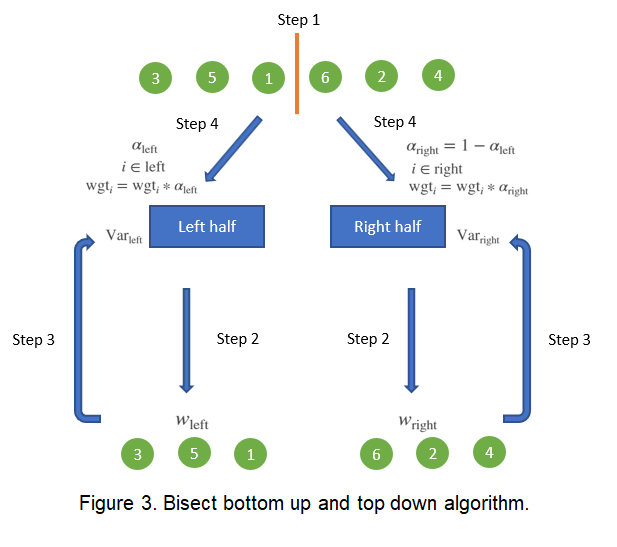

Function *helperBisectHRP* implements the recursive algorithm. It requires the covariance matrix of the original unsorted assets and the sorted asset list from the hierarchical tree structure.

wgt = helperBisectHRP(assetCovar, sortedIdx)

wgt =     0.0841
    0.0482
    0.0513
    0.0518
    0.1787
    0.1668
    0.0415
    0.0385
    0.0721
    0.0657


#### Compare HRP to Mean-Variance

All the implementation details are wrapped in *allocByBisectHierRiskParity* function, which includes computing distance matrix, building the clustering tree structure and allocating the weights with bisection algorithm. Here you can compare HRP's results with allocations found by Portfolio class in Financial Toolbox [Ref 3].

wgtHRP = allocByBisectHRP(assetCovar);

pMV = Portfolio('AssetCovar', assetCovar, 'AssetMean', mean(assetRetn), 'lb', 0, 'ub', 1, 'budget', 1);
wgtMV = estimateFrontierLimits(pMV, 'min');

Here you can visualize the resulting allocations from the two strategies. 

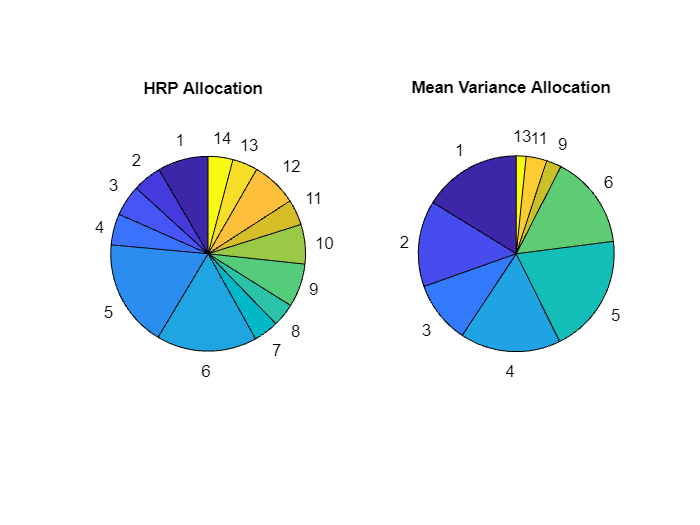

a = num2cell([1:nAssets]);
labels = cellfun(@(x) num2str(x),a', 'UniformOutput', false);
ax1 = subplot(1,2,1);
pie(ax1,wgtHRP(wgtHRP>0),labels(wgtHRP>0))
title(ax1,'HRP Allocation','Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
pie(ax2,wgtMV(wgtMV>0),labels(wgtMV>0))
title(ax2,'Mean Variance Allocation' ,'Position', [-0.05, 1.6, 0]);

wgtTable = array2table([wgtHRP, wgtMV], 'VariableNames', {'HRP', 'MeanVariance'})

wgtTable = 14×2 table
      HRP       MeanVariance
    ________    ____________

    0.084052       0.16224  
    0.048225       0.14195  
    0.051327       0.10276  
    0.051798       0.16618  
     0.17871       0.19717  
      0.1668       0.15435  
    0.041456             0  
    0.038503             0  
    0.072096      0.024952  
    0.065652             0  
    0.042585      0.034204  
    0.075679             0  
    0.042054      0.016192  
    0.041062             0  


You can see that HRP produces a much more diversified allocation as compared to Mean-Variance framework. Next step, you can backtest the HRP strategy against others and extract their performance metrics. 

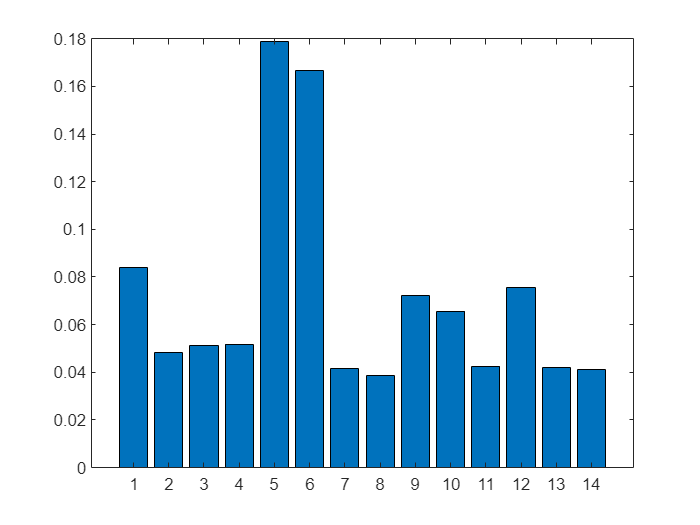

volHRP = std(assetRetn*wgtHRP);
volMV = std(assetRetn*wgtMV);
figure; bar(wgtHRP)

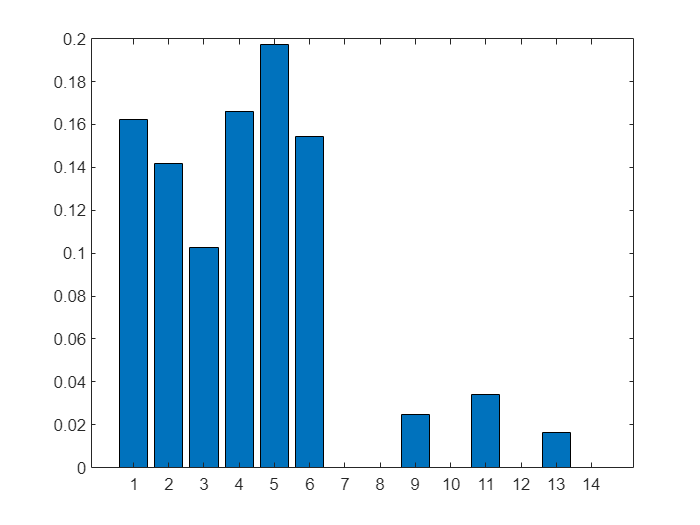

figure; bar(wgtMV)

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)